`Each row of ‘fea’ is a face and ‘gnd’ is the label`				

**This dataset has 38 individuals and around 64 near frontal images  **

clear
rng(1)
load YaleB_32x32.mat

`I. Randomly select 10,20,30,40,50 images per individual as training set. The rest are testing set. Use KNN (K=1) to predict test data and compute error rate.`

`Goal: plot error rate vs train image size per person`

YaleB = [fea, gnd];

K = 38;
m = [10,20,30,40,50]; %number of train data taken for each class
Error = [];
for q = m
    train_10 = [];
    test_10 = [];
    for i = 1:K
        G = YaleB(YaleB(:,1025) == i, 1:1025); % extract data of class i
        idx = randperm(size(G,1),q); %randomly generate q integers 1 to size(G,1)
        vec = [1: size(G,1)]; % Need this to extract test set
        test_idx = setdiff(vec,idx);

        test_set = G(test_idx,:);
        test_10 = [test_10; test_set];

    
        train = G(idx,:);
        train_10 = [train_10;train];
    end
    X_train = train_10(:,1:1024);
    Y_train = train_10(:,1025);
    X_test = test_10(:,1:1024);
    Y_test = test_10(:,1025);
    
    mdl_10 = fitcknn(X_train,Y_train, 'NumNeighbors',1); %train KNN
    
    predict_y_test = predict(mdl_10, X_test); %predict test data
    
    error_vec = predict_y_test ~= Y_test;
    Error_10 = (sum(error_vec) / size(Y_test,1)) * 100;
    Error = [Error, Error_10]


end

Error = 55.4572

Error =    55.4572   41.1729


Error =    55.4572   41.1729   35.6358


Error =    55.4572   41.1729   35.6358   26.8456


Error =    55.4572   41.1729   35.6358   26.8456   26.0700


figure
plot(m, Error,'o')
title('Prediction Error vs number of train images per person')

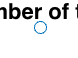

xlabel('Number of train images ')
ylabel('Error')

`II. `

`As we can see above, more training data provide more accurate prediction on test data.`

`Repeat the above procedure 50 training images per person for k = 1,2,3,5,10 and plot the error rate E against k.`

YaleB = [fea, gnd];
K = 38;
m = [10,20,30,40,50];

%Set up training set and testing set data
train_50 = [];
test_50 = [];
for i = 1:K
    G = YaleB(YaleB(:,1025) == i, 1:1025); % extract data of class i
    idx = randperm(size(G,1),m); %randomly generate m integers 1 to size(G,1)
    vec = [1: size(G,1)]; % Need this to extract test set
    test_idx = setdiff(vec,idx);

    test_set = G(test_idx,:);
    test_50 = [test_50; test_set];


    train = G(idx,:);
    train_50 = [train_50;train];
end
X_train_k = train_50(:,1:1024);
Y_train_k  = train_50(:,1025);
X_test_k  = test_50(:,1:1024);
Y_test_k  = test_50(:,1025);

% Start training KNN model and calculate error
Error_K = [];
k_vec = [1,2,3,5,10];
for k = k_vec
    mdl_k = fitcknn(X_train_k,Y_train_k, 'NumNeighbors',k); %train KNN
    predict_y_test = predict(mdl_k, X_test_k); %predict test data
    error_vec = predict_y_test ~= Y_test_k;
    Error_50 = (sum(error_vec) / size(Y_test_k,1)) * 100;
    Error_K = [Error_K, Error_50]
end

Error_K = 23.9300

Error_K =    23.9300   30.9339


Error_K =    23.9300   30.9339   31.7121


Error_K =    23.9300   30.9339   31.7121   31.3230


Error_K =    23.9300   30.9339   31.7121   31.3230   35.0195


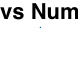


figure
plot(k_vec, Error_K)
title('Prediction Error vs Number of Neighbors')
xlabel('Number of K ')
ylabel('Error')


% Confusion Matrix
C = confusionmat(Y_test_k, predict_y_test); % known vs predict
confusionchart(C)

III. Let k = 3 and select m = 30, replace distance metric with |x - y|_p  p =1,3,5,10. Plot error vs p

% Perform Test Train split based on requirment 
K = 38;
m = 30; %number of train data taken for each class
train_30 = [];
test_30 = [];

for i = 1:K
    G = YaleB(YaleB(:,1025) == i, 1:1025); % extract data of class i
    idx = randperm(size(G,1),m); %randomly generate q integers 1 to size(G,1)
    vec = [1: size(G,1)]; % Need this to extract test set
    test_idx = setdiff(vec,idx);

    test_set = G(test_idx,:);
    test_30 = [test_30; test_set];


    train = G(idx,:);
    train_30 = [train_30;train];
end

X_train = train_30(:,1:1024);
Y_train = train_30(:,1025);
X_test = test_30(:,1:1024);
Y_test = test_30(:,1025);

Use minkowski to get |`x-y`|_p values.

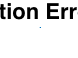

Error = [];
p_list = [1,3,5,10];
for p = p_list
    %train KNN
    model_p = fitcknn(X_train, Y_train, 'Distance', 'minkowski', 'NumNeighbors', 3);
    model_p.DistParameter = p;
    predict_y_test = predict(model_p, X_test);

    error_vec = predict_y_test ~= Y_test;
    Error_p = (sum(error_vec) / size(Y_test,1)) * 100;
    Error= [Error, Error_p];
end

%plot 
figure
plot(p_list, Error)
title('Prediction Error vs P')
xlabel('P ')
ylabel('Error')